x_n = [-4 -2 0 -4 -6 -4 -2 -4 -6 -6 ...
       -4 -4 -6 -6 -2 6 12 8 0 -16 ...
       -38 -60 -84 -90 -66 -32 -4 -2 -4 8 ...
       12 12 10 6 6 6 4 0 0 0 ...
       0 0 -2 -4 0 0 0 -2 -2 0 ...
       0 -2 -2 -2 -2 0]

x_n =     -4    -2     0    -4    -6    -4    -2    -4    -6    -6    -4    -4    -6    -6    -2     6    12     8     0   -16   -38   -60   -84   -90   -66   -32    -4    -2    -4     8    12    12    10     6     6     6     4     0     0     0     0     0    -2    -4     0     0     0    -2    -2     0


omegaP = .2*pi; omegaS = .3*pi; T =1; Fs = 1/T;
Rp = 1; As = 15;

OmegaP = 2*Fs * tan(omegaP/2);
OmegaS = 2*Fs * tan(omegaS/2);

[N, OmegaC] = buttord(OmegaP, OmegaS, Rp, As, 's')

N = 6

OmegaC = 0.7662

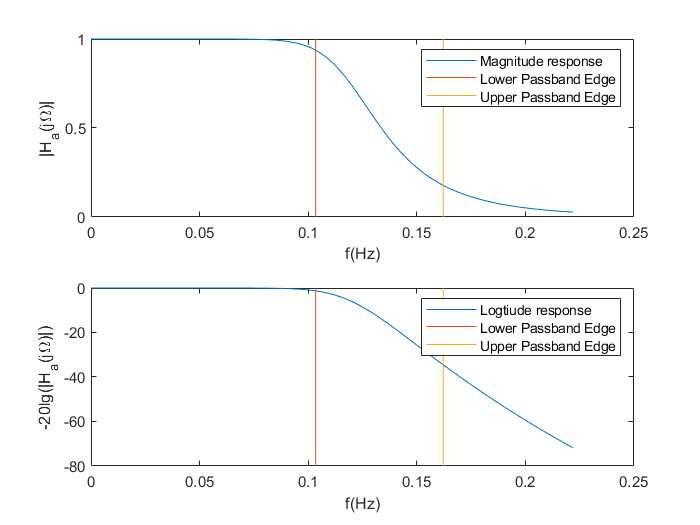


[b,a] = butter(N, OmegaC, 's');

[h, w] = freqs(b, a, linspace(0, OmegaC+.2*pi, 100));


[O1, O2] = meshgrid([OmegaP/(2*pi), OmegaS/(2*pi)], ylim);
subplot(2, 1, 1)
plot(w/(2*pi), abs(h))

hold on
plot(O1, O2)
hold off

xlabel('f(Hz)')
ylabel('|H_a(j\Omega)|')
legend('Magnitude response','Lower Passband Edge','Upper Passband Edge')

subplot(2, 1, 2)
plot(w/(2*pi), 20*log(abs(h)))

hold on
[O1, O2] = meshgrid([OmegaP/(2*pi), OmegaS/(2*pi)], ylim);
plot(O1, O2)
hold off

xlabel('f(Hz)')
ylabel('-20lg(|H_a(j\Omega)|)')
legend('Logtiude response','Lower Passband Edge','Upper Passband Edge')


[zb, za] = bilinear(b, a, Fs);

[sos, g] = tf2sos(zb, za)

sos =     1.0000    2.0003    0.9999    1.0000   -0.9044    0.2155
    1.0000    2.0178    1.0181    1.0000   -1.0106    0.3583
    1.0000    1.9820    0.9823    1.0000   -1.2686    0.7051


g = 7.3782e-04

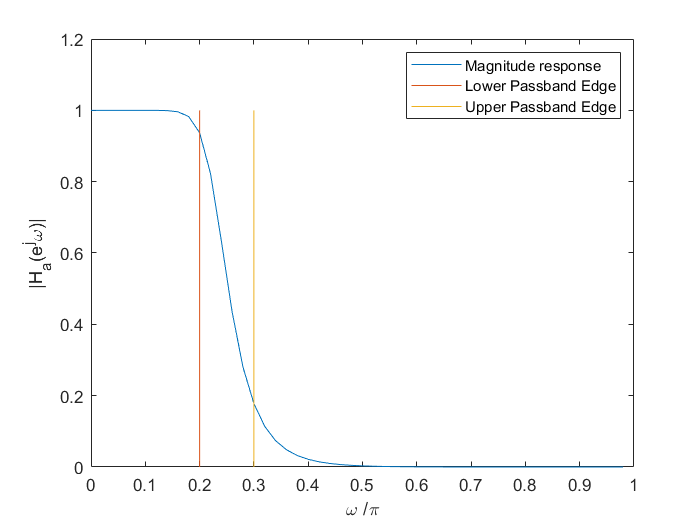


[h, w] = freqz(zb, za, 100, 'whole');
mag_h = abs(h);
figure
[o1, o2] = meshgrid([omegaP/(pi), omegaS/(pi)], ylim);
plot(w(1:50)/pi, mag_h(1:50))
hold on
plot(o1, o2)
hold off

legend('Magnitude response','Lower Passband Edge','Upper Passband Edge')
xlabel('\omega /\pi')
ylabel('|H_a(e^j\omega)|')

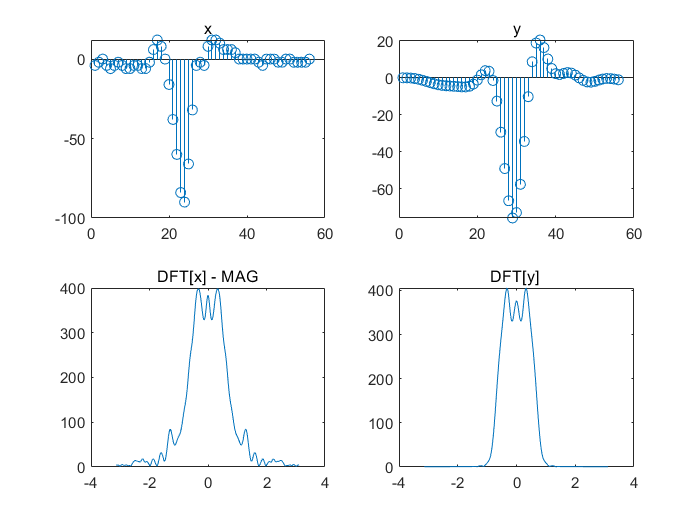

y_n = filter(zb, za, x_n);
N = 256;
n = floor(-(N-1)/2:(N-1)/2);
n = n*2*pi/N;

figure
subplot(2, 2, 1)
stem(x_n)
title('x')
subplot(2, 2, 2)
stem(y_n)
title('y')

subplot(2, 2, 3)
X = abs(fftshift(fft(x_n, N)));
plot(n, X)
title('DFT[x] - MAG')

subplot(2, 2, 4)
Y = abs(fftshift(fft(y_n, N)));
plot(n, Y)
title('DFT[y] ')

% function [bz, az] = bilinear(b, a, Fs)
%     M = length(b)-1;
%     N = length(a)-1;
%     L = N - M;
%     if L > 0
%         b = [zeros(1, L), b];
%     else a = [zeros(1, -L), a];
%     end
%     
%     Nz = 2*Fs*[1, -1];
%     Dz = [1, 1];
%     
%     N = max(N, M);
%     bz = 0;
%     az = 0;
%     
%     for k = 0:N
%         pld = [1];
%         pln = [1];
%         
%         for m=0:k-1
%             pld = conv(pld, Dz);
%         end
%         
%         for m=0:N-k-1
%             pln = conv(pln, Nz);
%         end
%         
%         bz = bz + b(k+1)*conv(pln, pld);
%         az = az + a(k+1)*conv(pln, pld);
%     end
%     
%     az = az/az(1);
%     bz = bz/bz(1);
% end